# Laboratorio 1 Robótica: Análisis Geométrico Directo de Manipuladores

## Universidad Nacional de Colombia

## Alejandro Ojeda Olarte, Brayan Calderon, Mateo Rodriguez

## Parte I | Robot

El robot asignado es el modelo UR3 de la empresa Universal Robots.

### Características y modelo del robot

####            1. Busque información técnica del robot, obtenga catálogos de fabricante, presente en el informe:

####                 a) Imagen del robot.

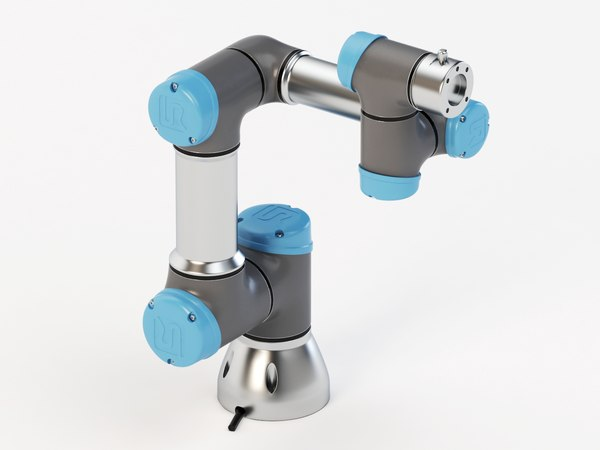

Universal Robot UR3 

####                 b)  Capacidad de carga.

                    Carga Util: 3Kg

####                 c)  Alcance vertical y horizontal.

                    Tiene un alcance de 500mm tanto vertical como horizontal

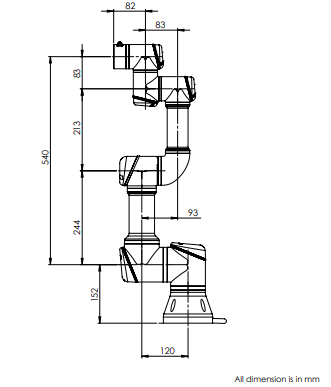

####                 d)  Repetibilidad.

                    Tiene una repetibilidad de  +/- 0.1mm 

####                  e)  Gráfica(s) de espacio alcanzable.

    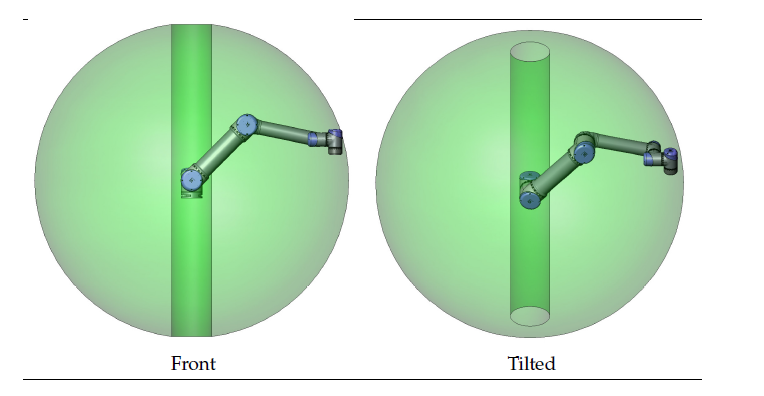

Espacio Alcanzable por el UR3

####                 f)  Tabla de parámetros DH.

                    - La siguiente tabla corresponde a los parámetros DH estándar suministrados por Universal Robots

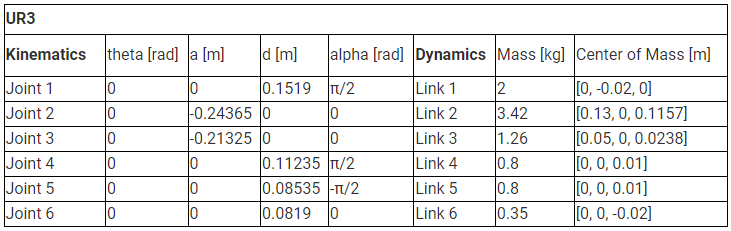

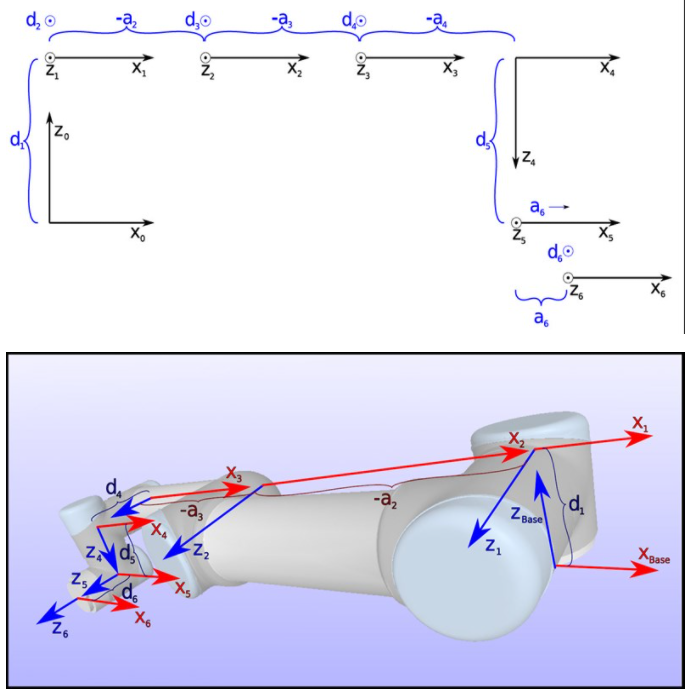

####                 g)  Qué software utiliza el fabricante para diseño de celdas o programación.

                        Polyscope -  https://www.universal-robots.com/download/?query=

####                 h)  ¿Qué otras características tiene? (Grado de protección IP, colaborativo, normas de seguridad etc.)

                        Grado de Protección IP64 IP54 (E67ON_Global). Es colaborativo y tiene 15 funciones avanzadas ajustables. De acuerdo con: ISO13849-1:2008, Pld y en ISO 10218-1:2011, cláusula 5.10.5. Las normas de seguridad asociadas al robot son: EC 60204-1, IEC60947-5-1 (direct acting contacts), ISO 13850 and ISO 13849-1. Certificado por TÜV NORD SS1 (Safe Stop 1)according to IEC 615800-        5-2, IEC61784-3, 61800-5-2

####                 i)  Haga un análisis del diagrama de la capacidad de carga.

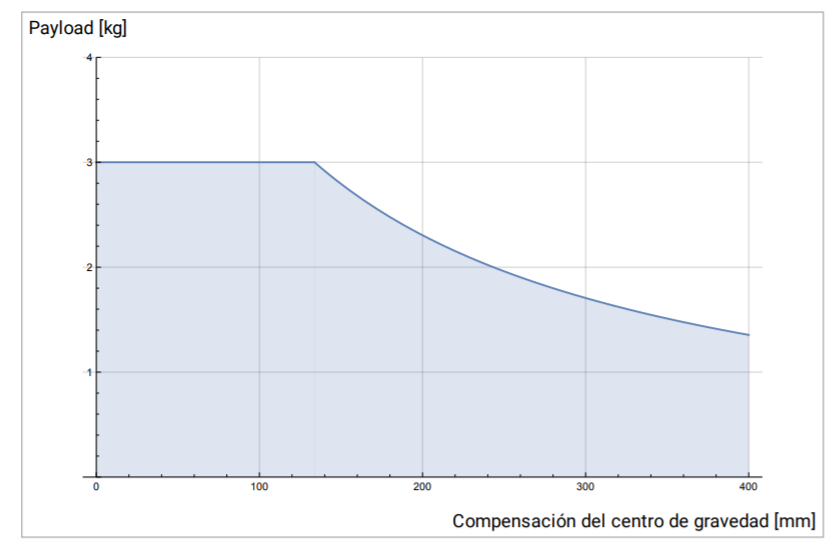

            La capacidad de carga del robot está ligada a la compensación del centro de gravedad, por tanto a mayor distancia este separada la carga de la base del robot, menor será el peso que puede soportar este.

####             2. Según las características anteriores explique para qué aplicaciones se usa este robot.

            Debido a su pequeño tamaño, está dirigido a aplicaciones que no requieren tanta carga mecanica, aplicaciones como: soldadura, en aplicaciones de pegado, aplicaciones de atornillamiento, de pintura, de pick and place, de operación de herramientas de mano, trabajo en laboratorios, y aplicaciones donde existen gases toxicos.

## Parte II | Modelos

### lniciando

#### Haciendo uso de MATLAB`® `y los toolboxes construya un modelo del robot o utilice uno disponible en los toolboxes y que corresponda al robot asignado.

####     1.Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.

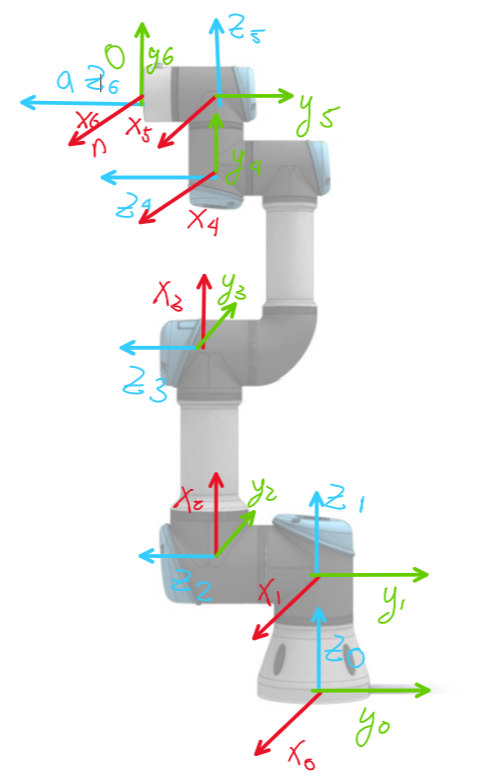

Tabla de parametros Denavit-Hartenberg


$$\left\lbrack \begin{array}{cccccc}
i & \alpha_{i-1}  & a_{i-1}  & d_i  & \theta_i  & \textrm{offset}\\
1 & 0 & 0 & 152 & \textrm{q1} & 0\\
2 & \frac{\pi }{2} & 0 & 120 & \textrm{q2} & \frac{\pi }{2}\\
3 & 0 & 244 & 0 & \textrm{q3} & 0\\
4 & 0 & 213 & -10 & \textrm{q4} & -\frac{\pi }{2}\\
5 & -\frac{\pi }{2} & 0 & 83 & \textrm{q5} & 0\\
6 & \frac{\pi }{2} & 0 & 82 & \textrm{q6} & 0
\end{array}\right\rbrack$$


%Creación de eslabones
L(1) = Link([0 0.152 0 0],'modified');
L(2) = Link([0 0.120 0 pi/2 0 pi/2],'modified');
L(3) = Link([0 0 0.244 0],'modified');
L(4) = Link([0 -0.010 0.213 0 0 -pi/2],'modified');
L(5) = Link([0 0.083 0 -pi/2],'modified');
L(6) = Link([0 0.082 0 pi/2],'modified');
R = SerialLink(L,'name','Universal Robot UR3')

 
R = 
 
Universal Robot UR3 (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.152|          0|          0|          0|
|  2|         q2|       0.12|          0|      1.571|      1.571|
|  3|         q3|          0|      0.244|          0|          0|
|  4|         q4|      -0.01|      0.213|          0|     -1.571|
|  5|         q5|      0.083|          0|     -1.571|          0|
|  6|         q6|      0.082|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
 

Aquí presentamos un modelo de alambres.

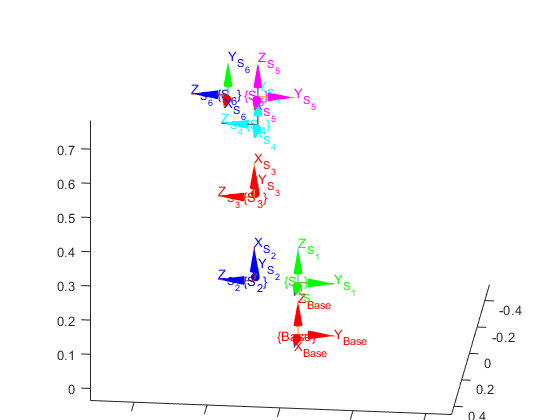

figure

hold on

s=0.1;
trplot(R.base,'length', s,'arrow','frame','Base','color','r')
trplot(R.base*L(1).A(0),'length', s,'arrow','frame','S_{1}','color','g')
trplot(R.base*L(1).A(0)*L(2).A(0),'length', s,'arrow','frame','S_{2}','color','b')
trplot(R.base*L(1).A(0)*L(2).A(0)*L(3).A(0),'length', s,'arrow','frame','S_{3}','color','r')
trplot(R.base*L(1).A(0)*L(2).A(0)*L(3).A(0)*L(4).A(0),'length', s,'arrow','frame','S_{4}','color','c');
trplot(R.base*L(1).A(0)*L(2).A(0)*L(3).A(0)*L(4).A(0)*L(5).A(0),'length', s,'arrow','frame','S_{5}','color','m');
trplot(L(1).A(0)*L(2).A(0)*L(3).A(0)*L(4).A(0)*L(5).A(0)*L(6).A(0),'length', s,'arrow','frame','S_{6}','rgb')

xlim([-0.521 0.464])
ylim([-0.52 0.47])
zlim([-0.036 0.784])
view([96.105 21.239])

Y se observa el modelo del robot.

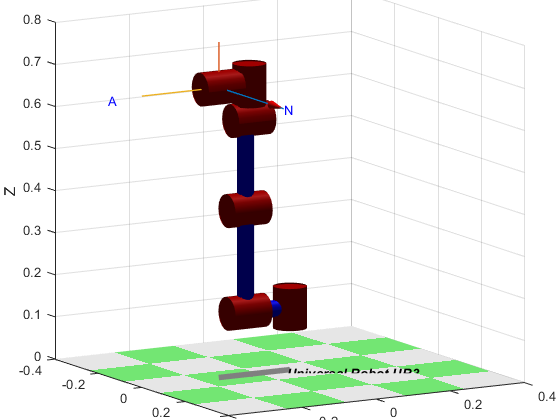

figure
R.plot([0 0 0 0 0 0],'workspace',[-0.4 0.4 -0.4 0.4 0 0.8], 'noa','view',[59.733 11.020])

#### 2.Considerando el robot asignado, construya el modelo del robot utilizando RST.

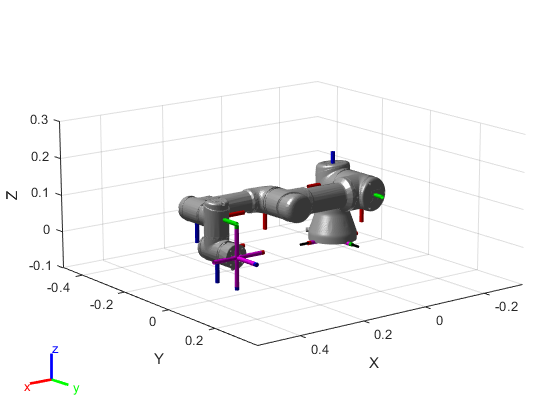

UR3=loadrobot("universalUR3");
show(UR3);

xlim([-0.336 0.528])
ylim([-0.491 0.373])
zlim([-0.1 0.3])
view([142.295 14.215])

showdetails(UR3)

--------------------
Robot: (10 bodies)

 Idx             Body Name                            Joint Name                            Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                            ----------                            ----------             ----------------   ----------------
   1             base_link                           world_joint                                 fixed                     world(0)   base(2)  shoulder_link(3)  
   2                  base            base_link-base_fixed_joint                                 fixed                 base_link(1)   
   3         shoulder_link                    shoulder_pan_joint                              revolute                 base_link(1)   upper_arm_link(4)  
   4        upper_arm_link                   shoulder_lift_joint                              revolute             shoulder_link(3)   forearm_link(5)  
   5          forearm_link                           e

####     3.Compare los dos métodos.

La metodología por el RVC (Robotics, Vision & Control) permite tener un análisis matemático mas detallado, puesto que esta construido a partir de parámetros de Denavid-Hartenberg, sin embargo solo corresponde a una representación matemática, de manera que se limita en condiciones físicas como colisiones. El método por el RST (Robotics System Toolbox) , permite configurar el robot de manera más fiel a la real, con modelos 3D, y eslabones como está construido el robot en realidad. A pesar de considerar cada eslabón como un cuerpo rígido, si habilita opciones como masa, inercia, centro de masa y cálculo de torques en cada motor.

Una diferencia importante es que en el RST, se configura una posición de Home desde el inicio, a pesar de que ambos se construyen ubicando puntos de referencia en base al eslabón anterior, y luego se agrupan esos elabones para tener un cuerpo rigido, un "RigiBody".

### Modelo Geométrico Directo 

####     1. Halle el modelo geométrico directo de su robot asignado usando DH modificado.

R

 
R = 
 
Universal Robot UR3 (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.152|          0|          0|          0|
|  2|         q2|       0.12|          0|      1.571|      1.571|
|  3|         q3|          0|      0.244|          0|          0|
|  4|         q4|      -0.01|      0.213|          0|     -1.571|
|  5|         q5|      0.083|          0|     -1.571|          0|
|  6|         q6|      0.082|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
 

####     2.  Haciendo uso del modelo directo haga una representación del espacio de trabajo alcanzable del robot.

s = 2*pi;

Unrecognized function or variable 'Link'.

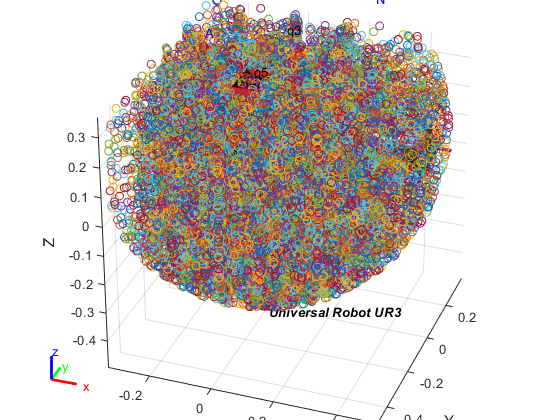

step=0.5;
hold on
for i = 0:step:s
    for j = 0:step:s
        for k = 0:step:s
            for m = 0:step:s
                for n = 0:step:s
                    endeffect=R.base*L(1).A(i)*L(2).A(j)*L(3).A(k)*L(4).A(m)*L(5).A(n)*L(6).A(0);
                    position=endeffect(1:3,4);
                    plot3(position(1),position(2),position(3),'o');
                end
            end
        end
    end
end

#### 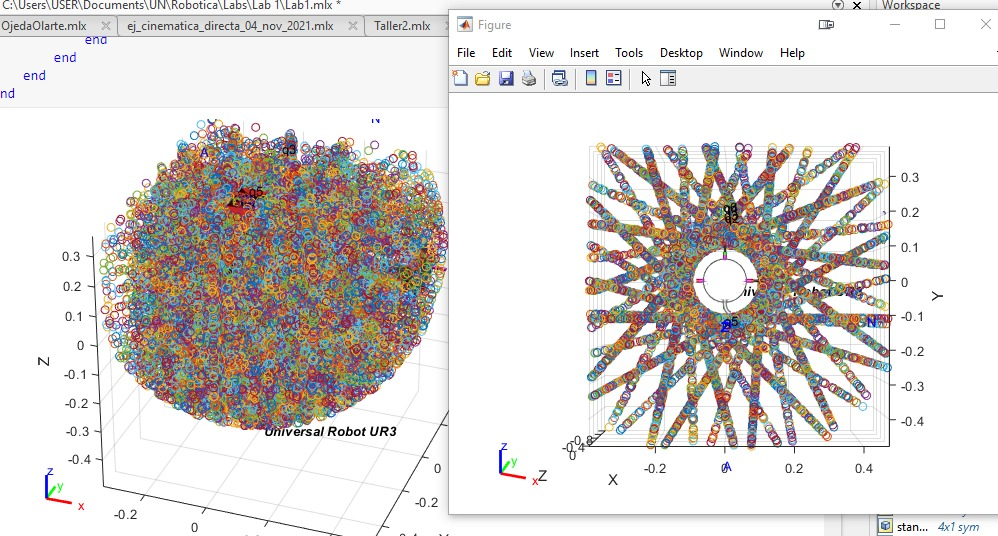 

####    3.  Con la hoja técnica del robot, el fabricante provee puntos de calibración. Con la ayuda de la cinemática directa verifique dichos puntos.

####     4.  Haga uso de las funciones de cinemática directa de ambos toolboxes y compruebe los resultados anteriores.

####     5.  Compare los métodos.

####     6.  Exprese la pose del efector en matriz de cosenos directores.

####     7.  Exprese la pose del efector final en coordenadas generalizadas del efector final.

####     8.  Elija uno de los métodos anteriormente usados y desarrolle una GUI que permita mover cada articulación mediante controles tipo Slider, visualizar el robot y la posición del efector final.

####     9.  En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones.